%Q1
%Wn^2/(s^2   +   2zWs + Wn^2)
%(1/m)/(s^2  +   B/m*s + K/m)

%parameters
%Range of m∈(0,1/64) = R
%As a result of m being in value in R the other parameters have ranges
%since they depend on m solely (m is free variable)
%therefore z∈(0,1), w∈( 1/0 , 8)
%note the first value of m was chosen arbitrarily
m=1/250;
K=1;
z = 8*sqrt(m);
w = 1/sqrt(m);

%transfer function of the system
sys = tf(w^2, [1 2*z*w w^2])

sys =
 
        250
  ----------------
  s^2 + 16 s + 250
 
Continuous-time transfer function.




%time
start = 0;
final = 2;
scale = 1000;
t = linspace(start,final,final*scale);

%step function input + graph
[y,t2] = step(sys,t); 
s = stepinfo(sys) %settling time is about right

s = struct with fields:
         RiseTime: 0.1044
    TransientTime: 0.5069
     SettlingTime: 0.5069
      SettlingMin: 0.9173
      SettlingMax: 1.1584
        Overshoot: 15.8370
       Undershoot: 0
             Peak: 1.1584
         PeakTime: 0.2303


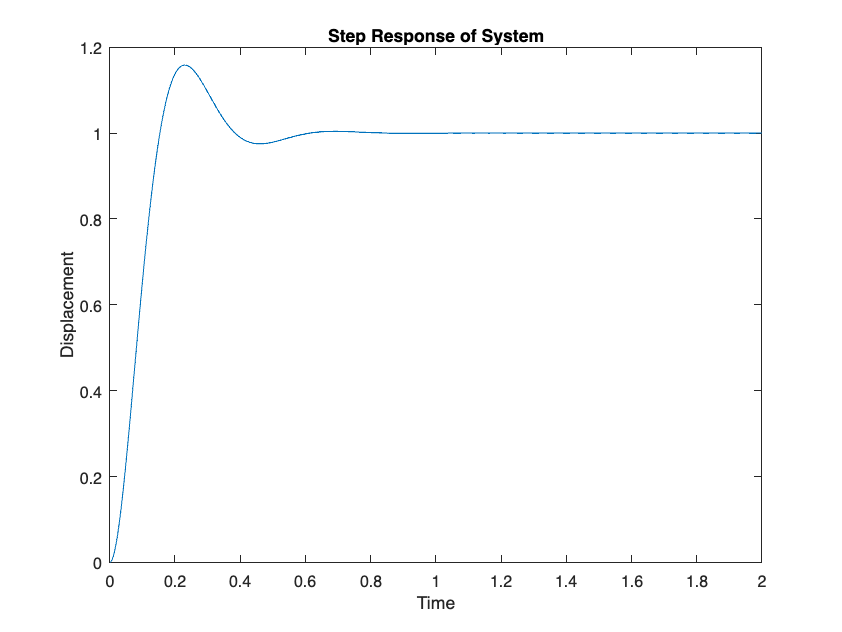

plot(t2, y)
title('Step Response of System')
xlabel('Time')
ylabel('Displacement')

%Q2
%ramp function input + graph of response

m=1/250;
z = 8*sqrt(m);
w = 1/sqrt(m);


%time
start = 0;
final = 2;
scale = 1000;
t2 = linspace(start,final,final*scale);

%divide by s then do step response since the
%resulting effect is to divide by s^2 which
%is a ramp input
sys2 = tf(w^2, [1 2*z*w w^2, 0])

sys2 =
 
          250
  --------------------
  s^3 + 16 s^2 + 250 s
 
Continuous-time transfer function.



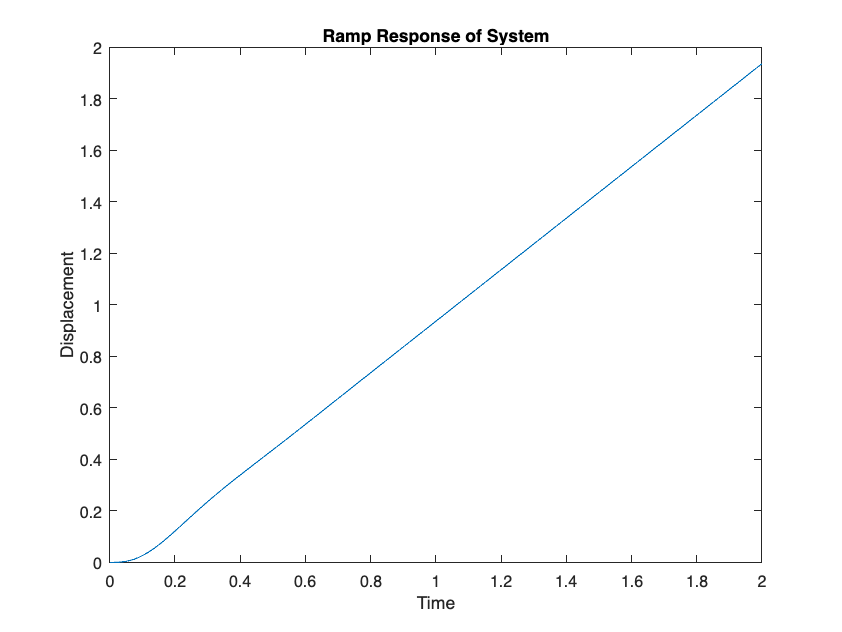

[y2,t3] = step(sys2,t); 

%graph
plot(t2, y2)
title('Ramp Response of System')
xlabel('Time')
ylabel('Displacement')